## 2. gyakorlat

#### 1. Feladat (HF)

Adjunk becslést az $A=\left[\begin{array}{cc} 4 & -0.5 \\ 0.1 & 2  \end{array}\right]$ mátrix sajátértékeire normával és a Gersgorin-tétel segítségével! 

% Megoldás

A=[4, -0.5; 0.1, 2];
R=min([norm(A,1), norm(A,inf), norm(A,'fro')]);
fprintf('A sajátértékei az origó körüli %f sugarú körben találhatók.',R);

A sajátértékei az origó körüli 4.100000 sugarú körben találhatók.


fprintf('A sajátértékei a következő körök uniójában találhatók: \n');

A sajátértékei a következő körök uniójában találhatók: 


fprintf('  1.  Középpont: %f,   Sugár: %f;\n', A(1,1), abs(A(1,2)));

  1.  Középpont: 4.000000,   Sugár: 0.500000;


fprintf('  2.  Középpont: %f,   Sugár: %f;\n', A(2,2), abs(A(2,1)));

  2.  Középpont: 2.000000,   Sugár: 0.100000;



l=eig(A);
fprintf('A sajátértékei: %f, %f\n', l(1),l(2))

A sajátértékei: 3.974679, 2.025321


#### 2. Feladat

a) Adjunk becslést az alábbi (szimmetrikus) mátrix sajátértékeire a Gersgorin-tétellel! 


$$A=\left[\begin{array}{cc} 2 & 0.1 \\ 0.1 & 1  \end{array}\right]$$


b) A 2 közelében lévő sajátértékre adjunk jobb becslést egy paraméteres hasonlósági transzformációval!

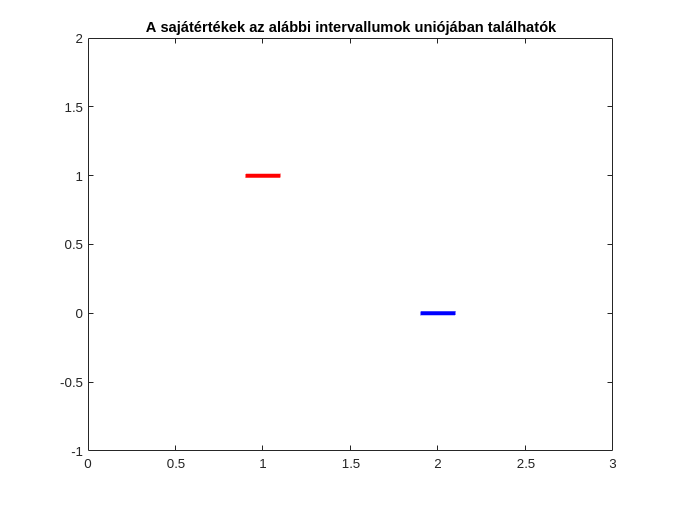

% Megoldás

A=[2,0.1; 0.1,1];

d=1;

D=[d,0; 0,1];
B=D\A*D;
i11=B(1,1)-B(1,2);
i12=B(1,1)+B(1,2);
i21=B(2,2)-B(2,1);
i22=B(2,2)+B(2,1);

plot([i11,i12],[0,0],'b-','LineWidth',3)
hold on
plot([i21,i22],[1,1],'r-','LineWidth',3)
hold off
axis([0,3,-1,2])
% axis([1.95,2.05,-1,2])
title('A sajátértékek az alábbi intervallumok uniójában találhatók')

**3. Feladat (HF)**

a) Adjunk becslést az alábbi mátrix sajátértékeire a Gersgorin-tétel segítségével! 


$$A=\left[\begin{array}{ccc} 8 & 6 & 3  \\ 1 & 4 &  -1 \\ -1 & 2& 5 \end{array}\right]$$


b) Végezzünk el $A$-n egy $B=D^{-1}AD$ hasonlósági transzformációt, ahol $D:=\textrm{diag}(3,2,2)$, majd adjunk újabb becslést a Gersgorin tétellel! 

c) Igazoljuk, hogy  invertálható!

% Megoldás

A=[8,6,3; 1,4,-1; -1,2,5];

% D=eye(3);
D=diag([3,2,2]);
B=D\A*D;

R1=sum(abs(B(1,[2,3])));
R2=sum(abs(B(2,[3,1])));
R3=sum(abs(B(3,[1,2])));
fprintf('A sajátértékei a következő körök uniójában találhatók: \n');

A sajátértékei a következő körök uniójában találhatók: 


fprintf('  1.  Középpont: %f,   Sugár: %f;\n', A(1,1), R1);

  1.  Középpont: 8.000000,   Sugár: 6.000000;


fprintf('  2.  Középpont: %f,   Sugár: %f;\n', A(2,2), R2);

  2.  Középpont: 4.000000,   Sugár: 2.500000;


fprintf('  3.  Középpont: %f,   Sugár: %f;\n', A(3,3), R3);

  3.  Középpont: 5.000000,   Sugár: 3.500000;


#### 4. feladat

Milyen becslést adhatunk Gersgorin-tétellel az $A$ sajátértékeire, ha tudjuk, hogy $\forall i\neq j ~:~ |a_{ij}| \leq \varepsilon$ és $\varepsilon \ll 1$?

#### 5. feladat

a) Az$A=\left[\begin{array}{cc} 
2 & -1 \\ -1 & 2  \end{array}\right]$ mátrix közelítő sajátértékeinek és sajátvektorainak ismeretében készítsük el a sajátértékek becslését a reziduális hibával!


$$\min |\lambda_i - \mu | \leq \frac{\|r\|}{\|\mu\|} \mathrm{cond}(X) \qquad \Big(X^{-1} A X = D=\mathrm{diag}(\lambda_1,\dots,\lambda_n), ~~
r=Au-\mu u \Big).$$


*(A kiindulásként vett közelítések hatvány-módszerrel kapott értékek, melyet hamarosan tanulunk.)* 

    i) $\mu=\frac{5}{2}, \quad
u=\left[\begin{array}{c} 5\\-4\end{array} \right],$ a pontos hiba: $\frac{1}{2}$.

    ii) $\mu=\frac{14}{5}, \quad
u=\left[\begin{array}{c} 5\\-4\end{array} \right],$ a pontos hiba: $\frac{1}{5}$.

b) Igazoljuk a Gersgorin-tétel segítségével, hogy $A$ pozitív definit mátrix!

%a
A=[2,-1;-1,2]

A =      2    -1
    -1     2


%i
u=[5;-4];
mu=5/2;
r=A*u-mu*u;
norm(r)/norm(u)

ans = 0.5238


%ii
u=[5;-4];
mu=14/5;
r=A*u-mu*u;
norm(r)/norm(u)

ans = 0.2811

### **Schur-felbontás**

`R=schur(A)`

`[Q,R] = schur(A) : `$R=Q^T A Q  \iff A=QRQ^T$ valós felbontás

`[Q,R] = schur(A,'complex') : `valós $A$ esetén komplex felbontást kérünk

#### **6. Feladat (HF)**

Készítsük el a következő mátrixok Schur-felbontását és adjuk meg a sajátértékeit, sajátvektorait!

`A=[-2,0,0;-5,-2,-5;5,0,3]`

`A=[4,0,0;8,4,8;0,0,4]`

`A=[0,-1; 1,0] `

% Megoldás
A=[-2,0,0;-5,-2,-5;5,0,3]

A =     -2     0     0
    -5    -2    -5
     5     0     3


[Q,R] = schur(A)

Q =          0   -0.9497   -0.3133
    0.7071   -0.2215    0.6715
   -0.7071   -0.2215    0.6715


R =     3.0000    8.2816   -2.5328
         0   -2.0000   -0.0000
         0    0.0000   -2.0000


schur(A)

ans =     3.0000    8.2816   -2.5328
         0   -2.0000   -0.0000
         0    0.0000   -2.0000



A=[4,0,0;8,4,8;0,0,4]

A =      4     0     0
     8     4     8
     0     0     4


[Q,R] = schur(A)

Q =      0    -1     0
     1     0     0
     0     0     1


R =      4    -8     8
     0     4     0
     0     0     4


schur(A)

ans =      4    -8     8
     0     4     0
     0     0     4



A=[0,-1; 1,0]

A =      0    -1
     1     0


[Q,R] = schur(A)

Q =      1     0
     0     1


R =      0    -1
     1     0


[Q,R] = schur(A,'complex')

Q =    0.0000 + 0.7071i  -0.7071 + 0.0000i
   0.7071 + 0.0000i   0.0000 - 0.7071i


R =    0.0000 + 1.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i


### Polinomok, sajátértékek

`poly(x) :` az $(x-x_1)(x-x_2) \cdots (x-x_n)$ polinom együtthatói

`poly(A) :` az $A$ mátrix karakterisztikus polinomjának együtthatói

`roots(poly(A)) : az `$A$ mátrix sajátértékei

`eig(A) :` `az `$A$ mátrix sajátértékei

`[V,D] = eig(A) : Az `$A$-t diagonalizáló $V$mátrix és a sajátértékeket tartalmazó $D$ diagonális mátrix. Ha $A$ diagonalizálható: $A=V D V^{-1}$.

`V*D/V :` osztás a $V$ mátrixszal = jobbról szorzás a $V$ mátrix inverzével!

p=[1,-2,1] % x^2-2*x+1 polinom

p =      1    -2     1


p(1) % főegyüttható

ans = 1

polyval(p,1) % helyettesítési érték

ans = 0

x=-2:2

x =     -2    -1     0     1     2


polyval(p,x)

ans =      9     4     1     0     1



poly(x)

ans =      1     0    -5     0     4     0


A=[2,-1;-1,2]

A =      2    -1
    -1     2


eig(A)

ans =      1
     3


poly(A) % karakterisztikus polinom

ans =      1    -4     3


#### 7. feladat

Wilkinson híres példája: számítsuk ki a polinom együtthatóit, amelyek gyökei az $1,2,\dots,N$ számok, majd az így kapott polinomnak határozzuk meg a gyökeit. Nagy $N$-ek esetén mit tapasztalunk? Mi magyarázza a jelenséget?

% Megoldás
format long
N=20;
x=1:N;
p=poly(x)

p = 1.0e+19 *

   0.000000000000000  -0.000000000000000   0.000000000000002  -0.000000000000126   0.000000000005333  -0.000000000167228   0.000000004017177  -0.000000075611118   0.000001131027700  -0.000013558518290   0.000130753501054  -0.001014229986551   0.006303081209929  -0.031133364316139   0.120664780378037  -0.359997951794761   0.803781182264505  -1.287093124515099   1.380375975364070  -0.875294803676160   0.243290200817664


y=roots(p)

y =   19.999874055724192
  19.001295393676987
  17.993671562737585
  17.018541647321989
  15.959717574548915
  15.059326234074415
  13.930186454760916
  13.062663652011070
  11.958873995343460
  11.022464271003383


norm(sort(x)-sort(y'),'inf')

ans =    0.069813545239084


max(abs(sort(x)-sort(abs(y'))))

ans =    0.069813545239084


#### **8. Feladat**

Legyen $A = H D H^{-1}$, ahol $H$ a Hilbert mátrix, $D$ pedig diagonális mátrix. Legyen továbbá $\delta P$ egy véletlen perturbáló mátrix. Számoljuk ki az$A$ és $A+\delta P$ mátrixok sajátértékeinek eltérését!

% Megoldás

N=5;

H=hilb(N);
Hinv=invhilb(N);
D=diag(1:N);
A=H*D*Hinv;
l=eig(A);

p=0.002;
dP=p*(rand(N)-0.5);
lP=eig(A+dP);
max(abs(sort(l)-sort(lP)))

ans =    2.732554255058117


#### **9. Feladat**

Készítsük el az $A=tridiag(-1,2,-1)$ mátrixot (a `diag `utasítás segítségével) és határozzuk meg a sajátértékeit! Változtassuk meg véletlenszerűen az elemeit és vizsgáljuk meg a sajátértékek változását!

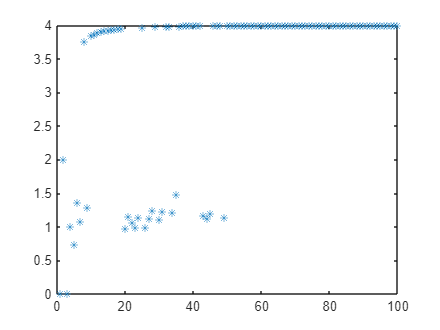

% Megoldás
N=100;
delta=zeros(1,N);

A=2*eye(N)-diag(ones(1,N-1),1)-diag(ones(1,N-1),-1);

p=0.002;
dP=p*(rand(N)-0.5);
dA=A+dP;
for k=2:N
    delta(k)=max(abs(eig(dA(1:k,1:k))-eig(A(1:k,1:k))));
end
plot(1:N,delta,'*')